# Kondition bei mehrfachen Nullstellen    

Wir betrachten $p_m\left(x\right):=x\left(x-3\right)^m$, $m=1,2,3$, mit einer $m$-fachen Nullstelle $x^\ast=3$. 

Wir werten jeweils folgende Darstellungen dieser Polynome aus:


$$\begin{array}{rcl}
  p_1(x)& =&x^2-3x\\
  p_2(x)& =&x^3-6x^2+9x \\
  p_3(x) &= &x^4-9x^3+27x^2-27x.
\end{array}$$


Wir wählen einen Wert  $m \in \{1,2,3\}$:

m=2

m =      2


Sei  $\delta$ etwa die Maschinengenauigkeit:

delta=10^(-15);

Wir wählen einen Wert $k\in \{1,2,\ldots,10\}$:

k=5;

und definieren die Schrittweite $h:=10^{k}\ast \delta$  und Stützstellen $x_i:=3 \pm i h$, $i=0, \ldots, 100$. 

Für die Auswertung des Polynoms $p_m(x_i)$ergibt sich dann folgendes Bild

-------------------

 Schrittweite bei der Auswertung:


h =    1.0000e-10


-------------------


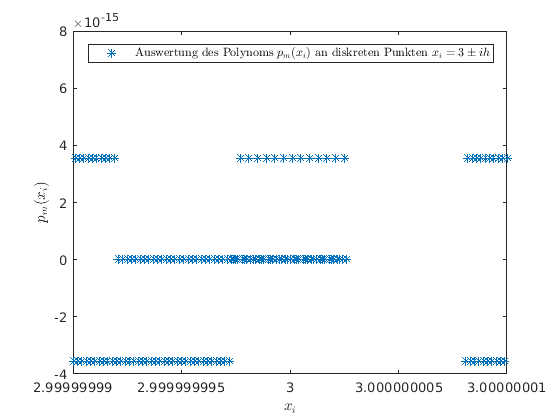

P(m,k,delta);

# Aktivität:

Sie können  $m$ und $k$ ändern und die Auswertung neu bestimmen.

function P(m,k,delta)
    x=zeros(1,201);
    disp('-------------------');
    fprintf('\n Schrittweite bei der Auswertung:\n');
    h = 10^k*delta
    for i=1:100
        x(i)=3-(101-i)*h;
    end
    for i=101:201
        x(i)=3+(i-101)*h;
    end
   
    switch m
        case 1
            y=x.*x-3*x;
        case 2
            y=x.*x.*x-6*x.*x+9*x;
        case 3
            y=x.*x.*x.*x-9*x.*x.*x+27*x.*x-27*x;
    end
    disp('-------------------');
    plot(x,y,'*');
    leg1=legend('Auswertung des Polynoms  $p_m(x_i)$ an diskreten Punkten  $x_i=3\pm i h$');
 set(leg1,'Interpreter','latex');
 xlabel('$x_i$','Interpreter','latex'); ylabel('$p_m(x_i)$','Interpreter','latex');
end
    